# 开始使用OmeBigTiff5D

本工具箱可以高速读写OME TIFF文件。仅支持Windows操作系统。

## TIFF与BigTiff

TIFF（Tag Image File Format，标签图像文件格式）是一种广泛使用的多图像存档文件格式，可以存储多张2D图像，每个像素也可以是1、2或4字节（称位深度或SizeP），它们线性排列在被称为IFD的维度（称I维度）上，每个IFD类似于视频的一“帧”，除了像素数值以外还包含高度（Y维度）、宽度（X维度）等元数据信息，每一项元数据被称为一个标签。TIFF规范规定了每个IFD都必须包含的，所谓必需标签，以及一些可选包含的标签。

经典的TIFF格式存在无法处理>4㎇文件的问题。BigTiff是TIFF格式的变体，解决了4㎇限制的问题。TIFF和BigTiff格式规范详见：[https://www.awaresystems.be/imaging/tiff.html](https://www.awaresystems.be/imaging/tiff.html)

## OME-TIFF

但是，很多时候，高、宽、IFD，这3个维度并不足以满足我们的需求，于是出现了OME（Open Microscopy Environment，开放显微镜环境）-TIFF扩展格式，将I维度扩展为C, Z, T三个维度：

- C，Channel，颜色通道。这里指的不是常见的RGB颜色通道，而是拍摄设备所支持的同时工作的记录设备。这些设备往往可以记录不同波长的光信号，包括但不限于RGB，甚至还包括非光学信号。

- Z，深度层级。许多拍摄设备可以对拍摄对象进行多层深度扫描拍摄，形成立体图像，因此需要增加一个Z维度。

- T，Time，时间轴。

这样，OME-TIFF实际上是具有XYCZT这5个维度的图像文件。为了与TIFF格式兼容，它利用了TIFF格式里可选的ImageDescription标签。OME-TIFF规定，在完全满足TIFF规范的基础上，首个IFD的ImageDescription标签变为必需标签。这个标签在TIFF规范中可以是任意的字符串，OME则规范了这个字符串必须为特定的OME-XML格式元数据，用于记录XYCZT各维度尺寸信息，各通道颜色（ChannelColor），各维度在存储空间中的线性排列顺序（DimensionOrder，谁为高维谁为低维），单个像素值的数据类型（PixelType），以及拍摄设备相关的元数据信息。OME规范详见：[https://docs.openmicroscopy.org/ome-model/6.2.2/ome-tiff/specification.html](https://docs.openmicroscopy.org/ome-model/6.2.2/ome-tiff/specification.html)

OME规范与TIFF/BigTiff的规范是正交的，即它既可以基于TIFF，也可以基于BigTiff。因此，传统的TIFF或BigTiff解析代码可以同样正确解读OME-TIFF，只是不能利用OME规范的额外功能而已。在传统代码眼中，OME-TIFF仍然只有XYI三个维度，其中I维度是由CZT三个维度展开而成。将I维度折叠成CZT三个维度所需的全部信息记录在ImageDescription中，折叠工作由支持OME规范的代码虚拟地完成，而不对I维度本身作任何改动。

但是，OME规范要求将5个维度的尺寸全部记录在首IFD标签中，这隐含地要求了所有IFD图像帧必须具有相同的高度、宽度和位深度；而一般的TIFF规范中无此要求，各个IFD可以独立设置各自的高度宽度。

## OmeBigTiff5D

上述TIFF格式及其各类变体，仍存在一个设计上的根本缺陷，即不支持随机访问。

文件中的字节是在地址空间中线性排列的，无论文件具有何种结构，这种结构都必须序列化为一串字节。TIFF规范在文件头中定义了首个IFD的字节偏移，即从文件起始开始向后多少个字节到达首个IFD；而IFD中的StripOffsets标签则记录了该IFD所对应的实际的像素数据的字节偏移；IFD结构的最后还记录了下一个IFD的字节偏移。也就是说，TIFF文件中的IFD维度并不是连续线性分布的，而是呈单向链表结构，只能从首IFD开始逐一寻找下一个IFD，直到最后一个IFD会指示它的下一个IFD的字节偏移为0，即本IFD是最后一个IFD。

链表结构的优势在于可以高效地插入和删除，但随机访问性能很差。虽然读取程序可以建立缓存来存储每个IFD实际像素数据的指针，但仍不能免于遍历目标IFD之前的所有IFD。

OmeBigTiff5D是作者在OME BigTiff基础上进一步严格格式规范：

- 紧接BigTiff文件头之后，字节偏移16的位置写入一个固定字节79，标志该文件遵守本规范

- IFD的标签可以是单个值，也可以指向文件的某个位置，表示该位置存储着该标签的值。因此首IFD的ImageDescription标签，在本规范中被要求指向所有IFD之前，紧接文件头之后。ImageDescription块与首IFD之间可以有任意大空隙，为后续扩展预留空间。

- 除首个IFD具有额外的ImageDescription，共计12个标签以外，其余每个IFD都有且仅有TIFF规范GrayScale图像的11个必需标签。这些标签按照固定顺序排列：ImageDescription（仅首IFD有）, StripOffsets, ImageWidth, ImageLength, BitsPerSample, RowsPerStrip, StripByteCounts, Compression, PhotometricInterpretation, XResolution, YResolution, ResolutionUnit。因为每个标签恰好占用20字节且紧密线性排列，所以每个IFD占用的字节也是固定的。

- 所有IFD必须按照顺序紧密线性排列，因此可以根据首IFD偏移直接算出任何一个IFD的偏移，无需遍历。而ImageDescription中记录了CZT尺寸信息，因此可用SizeC×SizeZ×SizeT=SizeI直接算出IFD总数，因而算出所有IFD占用的字节总数。

- 所有IFD对应的实际像素数据块，也必须按照维度顺序紧密线性排列。因此根据首IFD的StripOffsets，以及在ImageDescription中读到的SizeX×SizeY×SizeP算出每个IFD对应像素数据占用的字节数，进一步算出任意一个IFD的指针，同样无需遍历。此外，内存连续的像素数据块可以看作一个5D数组，进行高效的索引和向量化、并行拷贝操作。

- 像素块在IFD块之后，两者之间可以有任意大空隙，便于IFD扩展预留空间。像素块到文件尾之间也可适当留空隙。

本格式的优势是具有高效的随机访问性能，无需遍历即可计算出所需数据的正确位置，一步直达。缺点是需要在写入数据之前预分配足够的文件空间，如果写入过程中发现空间不足，需要将后续数据成员全部向后移动，并更改所有的文件指针，性能开销较大。但这仅限于在写入前无从得知数据量的情况，如果能在写入前得知数据大小并预分配充分大的存储空间，本格式的写入性能仍高于传统TIFF。

## 本工具箱提供的功能

对于传统的TIFF和OME格式，本工具箱只提供读取功能，不支持任何修改。对于BigTiff变体，将会在底层自动识别，对用户透明。

需要注意的是，本工具箱对文件作如下假定，这些假定在无论在TIFF还是OME规范中都是不作保证的：

- 假定所有IFD的SizeX SizeY SizeP均相同。因此只会读取首IFD的尺寸标签，后续IFD不再重复读取，而是直接视为和首IFD相同。如果你的图像文件不满足这个条件，将无法用本工具箱正确读取。

- 假定每个IFD内部的像素数据都是连续紧密排列的，即不存在任何一个IFD帧数据分布在文件中的多个不同位置，这等价于StripOffsets标签为单一值，RowsPerStrip=ImageLength

- 像素数据未经任何压缩，即StripByteCounts=SizeP×SizeX×SizeY，Compression为无压缩。

不要对不满足上述假定的文件使用本工具包，将造成意外结果。

尽管传统格式的像素数据不是连续紧密排列的（跨IFD时），因而需要遍历文件才能得到每个IFD的指针，但本工具箱会在遍历过程中将这些指针缓存下来，这样在遍历后可以得到接近随机访问的性能。这个过程对用户是透明的，用户可以调用本工具箱提供的ReadPixels3D和ReadPixels5D函数像访问MATLAB数组一样访问像素数据。

对于OmeBigTiff5D格式，本工具箱提供完整的随机读写功能：

- 继承自传统读取器的3D和5D读取函数，但实现了针对本格式的特殊优化

- WritePixels5D函数，像写出到MATLAB数组一样将像素数据写出到文件

- 随时修改任何基本尺寸参数，甚至直接重写图像描述

- 根据元数据直接算好并预分配文件占用空间，在写入任何像素数据之前就可以在Windows文件资源管理器中看到文件的最终尺寸。这种预分配策略相比于主流TIFF库“边写入边扩张文件”的策略，可以有效减少磁盘IO的开销。

- 生成的文件可以被完整支持OME BigTiff的阅读器正确读取，不需要专门阅读器。

但需要注意，为了追求性能，本工具箱在易用性上做出了一些牺牲。为了最小化这些牺牲造成的不便，请尽量采纳如下建议的使用方法：

- 修改现有文件的基本参数，比重新覆盖创建新文件性能更高，但是可能会破坏之前已经写入的像素数据。因此请尽量在写入任何像素之前确定好基本参数，如果必须要修改请确保像素数据有备份，修改后重新写入。如果要修过多个基本参数，请不要逐一修改，而是使用ModifyMultiParameters一次性修改完毕，减少文件结构调整的开销。

- 使用PixelPointer3D或PixelPointer5D返回的指针作为ReadPixels3D或ReadPixels5D的最后一个参数，可以不经过MATLAB数组中介直接完成文件拷贝，性能较高。也可以将源文件指针作为WritePixels5D的第1个参数。但需注意，传统TIFF读取器虽然也能返回指针，但不能进行跨IFD拷贝，因为其像素数据在IFD之间不是连续紧密排列的；因为其打开方式为只读，因此这些指针也不能接受写入的数据，只能作为数据源。

- 不同的文件可能具有不同的维度顺序（XY始终是最低的两个维度）。在维度顺序不同的文件之间拷贝数据，则无法使用指针直接对拷，必须经过MATLAB数组中转并permute到合适的维度顺序。

- 用MATLAB内置的imshow、imwrite等函数处理图像帧时，需注意MATLAB的图像维度顺序是YX，而文件中的维度顺序是XY，因此操作之前需要做矩阵转置，否则处理的是沿主对角线翻转的图像。

- XYCZT五个维度的最大尺寸限定为65535×65535×255×255×65535，如有更大需求请联系作者。

- 如果你使用ImageJ查看图像，需注意ImageJ存在一个已知bug，即无法正确处理含有红色分量的通道颜色。如果你的图像中含有红色分量的颜色通道，会导致ImageJ对整个 OME-XML ImageDescription 的读取都失败，因而整个图像的5D结构都将无法解析。本工具箱无法解决此问题，请向ImageJ开发人员反馈。

- OME规范要求文件名必须记录在 OME-XML ImageDescription 中。本工具箱会自动完成这项记录，但无法监视其它途径造成的文件名修改。如果需要修改文件名，请同步修改FileName属性，否则可能会造成某些阅读器无法正确阅读该文件。

## 工具箱结构

所有必要代码文件位于+OBT5命名空间下，对外暴露 OBT5.TiffReader, OBT5.OmeTiffReader, OBT5.OmeBigTiff5D 三个功能类，可使用doc函数查看各类详细说明。

## 用例

运行用例时将文件路径替换成你的文件路径

TIFF转OmeBigTiff5D

import OBT5.*
SourceTiff=TiffReader.Create('测试用例\测试图像.tif',true);
TargetTiff=OmeBigTiff5D.Create('测试用例\测试图像.5d.tif',CreationDisposition.Overwrite,512,512,1,2,60,DimensionOrder.XYCZT,PixelType.UINT16);
TargetTiff.ChannelColor(0x00ff00ff);
SourceTiff.ReadPixels3D(TargetTiff.PixelPointer3D);
clearvars TargetTiff SourceTiff

OME-TIFF转OmeBigTiff5D

import OBT5.*
SourceTiff=OmeTiffReader.Create('测试用例\测试图像.tif',true);
TargetTiff=OBT5.OmeBigTiff5D.Create('测试用例\测试图像.ob5.tif',OBT5.CreationDisposition.Overwrite,SourceTiff.ImageDescription);
SourceTiff.ReadPixels5D(TargetTiff.PixelPointer3D);
clearvars TargetTiff SourceTiff

ZC转置并变色

import OBT5.*
T5D=OmeBigTiff5D.Create('测试用例\测试图像.5d.tif',CreationDisposition.TryOpen);

错误使用 CheckPos (第 8 行)
打开文件失败

出错 OBT5.OmeBigTiff5D.Create (第 80 行)
			obj=OBT5.OmeBigTiff5D(CheckPos(POS));

T5D.ModifyMultiParameters(SizeC=2,SizeZ=1,Colors=[0x0000ffff 0x00ff00ff]);
clearvars T5D;

显示一帧

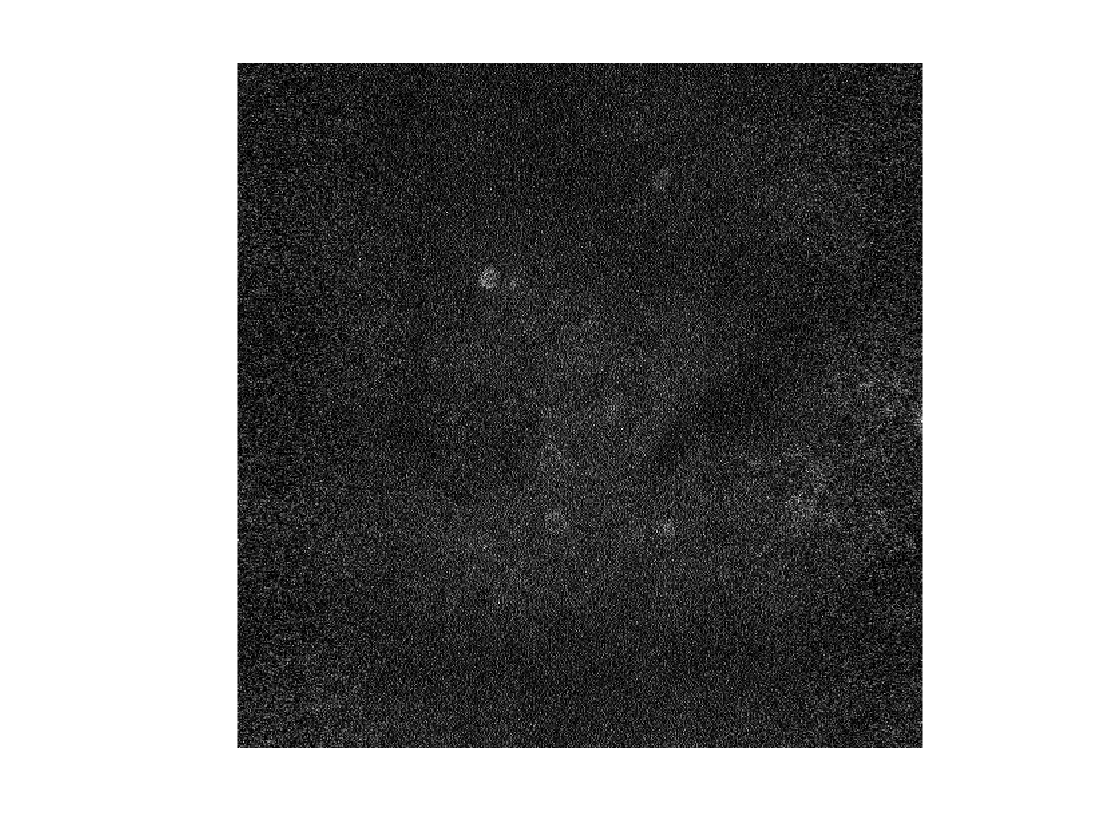

import OBT5.*
T5D=OmeBigTiff5D.Create('测试用例\测试图像.5d.tif',CreationDisposition.OpenExisting);
imshow(T5D.ReadPixels5D(C=0,Z=0,T=30)',[]);

clearvars T5D;